syms q1 q2 q3 x h % DOF
syms q1dot q2dot q3dot hdot xdot%
q = [q1; q2; q3; x; h];
qdot = [q1dot; q2dot; q3dot; xdot; hdot];

% DOF wrt t
syms qt1(t) qt2(t) qt3(t) ht(t) xt(t)
qt(t) = [qt1; qt2; qt3; xt; ht];

%Link Lengths
L1 = 1;
L2 = 1;
L3 = 1;

%Masses
density = 1;
Area = 1;
M1 = L1*density*Area;
M2 = L2*density*Area;
M3 = L3*density*Area;

M = [M1, M2, M3, 0];
%Theta
Th1 = q1;
Th2 = q1 + q2;
Th3 = q1 + q2 + q3;

%Relative End Posistions
OE1 = L1*[cos(Th1) sin(Th1)]

$$OE1 = \left(\begin{array}{cc} \cos\left(q_{1}\right) & \sin\left(q_{1}\right) \end{array}\right)$$

E1E2 = L2*[cos(Th2) sin(Th2)]

$$E1E2 = \left(\begin{array}{cc} \cos\left(q_{1}+q_{2}\right) & \sin\left(q_{1}+q_{2}\right) \end{array}\right)$$

E2E3 = L3*[cos(Th3) sin(Th3)]

$$E2E3 = \left(\begin{array}{cc} \cos\left(q_{1}+q_{2}+q_{3}\right) & \sin\left(q_{1}+q_{2}+q_{3}\right) \end{array}\right)$$


O = [0 0];
E1 = O + OE1;
E2 = E1 + E1E2;
E3 = E2 + E2E3;

C1 = O + .5*OE1;
C2 = E1 + .5*E1E2;
C3 = E2 + .5*E2E3;
C = [C1; C2; C3]

$$C = \left(\begin{array}{cc} \frac{\cos\left(q_{1}\right)}{2} & \frac{\sin\left(q_{1}\right)}{2}\\ \frac{\cos\left(q_{1}+q_{2}\right)}{2}+\cos\left(q_{1}\right) & \frac{\sin\left(q_{1}+q_{2}\right)}{2}+\sin\left(q_{1}\right)\\ \frac{\cos\left(q_{1}+q_{2}+q_{3}\right)}{2}+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right) & \frac{\sin\left(q_{1}+q_{2}+q_{3}\right)}{2}+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right) \end{array}\right)$$


%%
syms t

qt2(t) = pi/2*exp(-(t-5)^2)

$$qt2(t) = \frac{\pi \,{\mathrm{e}}^{-{\left(t-5\right)}^{2}}}{2}$$

qt3(t) = -pi/2*exp(-(t-5)^2)

$$qt3(t) = -\frac{\pi \,{\mathrm{e}}^{-{\left(t-5\right)}^{2}}}{2}$$

CMstart =subs(COM(C,M), [q2,q3], [qt2,qt3]);
CMstart = CMstart(1) == 0

$$CMstart = \cos\left(q_{1}\right)+\frac{\cos\left(q_{1}+\frac{\pi \,{\mathrm{e}}^{-{\left(t-5\right)}^{2}}}{2}\right)}{2}=0$$

assume(0<q1<pi)
assume(0<t)
q1start = solve(CMstart,q1,'ReturnConditions',true,'Real',true)

q1start = struct with fields:
            q1: [2×1 sym]
    parameters: [1×0 sym]
    conditions: [2×1 sym]


q1start.q1

$$ans = \begin{array}{l} \left(\begin{array}{c} -2\,\mathrm{atan}\left(\frac{\sigma_{2}-\sigma_{1}}{\sigma_{3}+2}\right)\\ -2\,\mathrm{atan}\left(\frac{\sigma_{2}+\sigma_{1}}{\sigma_{3}+2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{{\sigma_{3}}^{2}+4\,\sigma_{3}+{\sigma_{2}}^{2}+4}\\ \sigma_{2}=\sin\left(\frac{\pi \,{\mathrm{e}}^{10\,t}\,{\mathrm{e}}^{-25}\,{\mathrm{e}}^{-t^{2}}}{2}\right)\\ \sigma_{3}=\cos\left(\frac{\pi \,{\mathrm{e}}^{10\,t}\,{\mathrm{e}}^{-25}\,{\mathrm{e}}^{-t^{2}}}{2}\right) \end{array}$$

q1start.parameters

 
ans =
 
Empty sym: 1-by-0
 


q1start.conditions

$$ans = \begin{array}{l} \left(\begin{array}{c} \left(\sigma_{1}<0\wedge \sigma_{2}<0\right)\vee \left(\sigma_{1}<0\wedge 0\leq \sigma_{2}\right)\\ \left(\sigma_{1}<0\wedge \sigma_{2}<0\right)\vee \left(0\leq \sigma_{1}\wedge \sigma_{2}<0\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{atan}\left(\frac{\sigma_{3}-\sqrt{{\sigma_{4}}^{2}+4\,\sigma_{4}+{\sigma_{3}}^{2}+4}}{\sigma_{4}+2}\right)\\ \sigma_{2}=\mathrm{atan}\left(\frac{\sigma_{3}+\sqrt{{\sigma_{4}}^{2}+4\,\sigma_{4}+{\sigma_{3}}^{2}+4}}{\sigma_{4}+2}\right)\\ \sigma_{3}=\sin\left(\frac{\pi \,{\mathrm{e}}^{10\,t}\,{\mathrm{e}}^{-25}\,{\mathrm{e}}^{-t^{2}}}{2}\right)\\ \sigma_{4}=\cos\left(\frac{\pi \,{\mathrm{e}}^{10\,t}\,{\mathrm{e}}^{-25}\,{\mathrm{e}}^{-t^{2}}}{2}\right) \end{array}$$

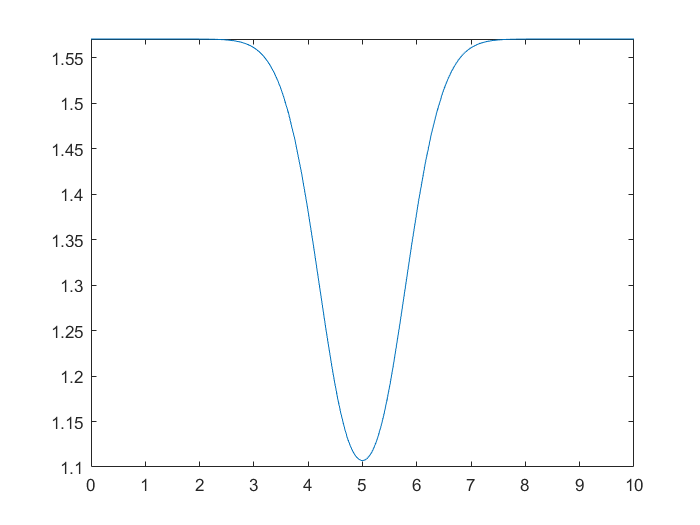

fplot(q1start.q1(1),[0,10])


qt1=subs(q1start.q1(1),q1start.parameters,0)

$$qt1 = \begin{array}{l} -2\,\mathrm{atan}\left(\frac{\sin\left(\frac{\pi \,{\mathrm{e}}^{10\,t}\,{\mathrm{e}}^{-25}\,{\mathrm{e}}^{-t^{2}}}{2}\right)-\sqrt{{\sigma_{1}}^{2}+4\,\sigma_{1}+{\sin\left(\frac{\pi \,{\mathrm{e}}^{10\,t}\,{\mathrm{e}}^{-25}\,{\mathrm{e}}^{-t^{2}}}{2}\right)}^{2}+4}}{\sigma_{1}+2}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{\pi \,{\mathrm{e}}^{10\,t}\,{\mathrm{e}}^{-25}\,{\mathrm{e}}^{-t^{2}}}{2}\right) \end{array}$$

Y_ref = [qt1,qt2,qt3,diff(qt1,t),diff(qt2,t),diff(qt3,t)].'

$$Y\_ref(t) = \begin{array}{l} \left(\begin{array}{c} -2\,\mathrm{atan}\left(\frac{\sin\left(\sigma_{6}\right)-\sigma_{2}}{\cos\left(\sigma_{6}\right)+2}\right)\\ \frac{\pi \,\sigma_{5}}{2}\\ -\frac{\pi \,\sigma_{5}}{2}\\ -\frac{2\,\left(\frac{\cos\left(\sigma_{6}\right)\,\sigma_{1}+\frac{2\,\sin\left(\sigma_{6}\right)\,\sigma_{1}}{\sigma_{2}}}{\cos\left(\sigma_{6}\right)+2}+\frac{\sin\left(\sigma_{6}\right)\,\sigma_{1}\,\left(\sin\left(\sigma_{6}\right)-\sigma_{2}\right)}{\sigma_{4}}\right)}{\frac{{\left(\sin\left(\sigma_{6}\right)-\sigma_{2}\right)}^{2}}{\sigma_{4}}+1}\\ -\sigma_{3}\\ \sigma_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=5\,\pi \,{\mathrm{e}}^{10\,t}\,{\mathrm{e}}^{-25}\,{\mathrm{e}}^{-t^{2}}-\pi \,t\,{\mathrm{e}}^{10\,t}\,{\mathrm{e}}^{-25}\,{\mathrm{e}}^{-t^{2}}\\ \sigma_{2}=\sqrt{{\cos\left(\sigma_{6}\right)}^{2}+4\,\cos\left(\sigma_{6}\right)+{\sin\left(\sigma_{6}\right)}^{2}+4}\\ \sigma_{3}=\frac{\pi \,\sigma_{5}\,\left(2\,t-10\right)}{2}\\ \sigma_{4}={\left(\cos\left(\sigma_{6}\right)+2\right)}^{2}\\ \sigma_{5}={\mathrm{e}}^{-{\left(t-5\right)}^{2}}\\ \sigma_{6}=\frac{\pi \,{\mathrm{e}}^{10\,t}\,{\mathrm{e}}^{-25}\,{\mathrm{e}}^{-t^{2}}}{2} \end{array}$$

matlabFunction(Y_ref,'File','Reference')

ans = function_handle with value:
    @Reference



syms T2 T3
VF = threedof_ground(T2,T3,[q(1:3);qdot(1:3)])


syms q2refddot q3refddot
torque = simplify(nonridgid_torque([q(1:3);qdot(1:3)],q2refddot,q3refddot))

CM_23 = [COM(C(2:3,:),M(2:3))];
tau = [(CM_23(1)-OE1(1))*(9.81)*(sum(M(2:3)));
    (C(3,1)-(OE1(1) + E1E2(1)))*(9.81)*(sum(M(3)))]

$$tau = \left(\begin{array}{c} \frac{981\,\cos\left(q_{1}+q_{2}+q_{3}\right)}{200}+\frac{2943\,\cos\left(q_{1}+q_{2}\right)}{200}\\ \frac{981\,\cos\left(q_{1}+q_{2}+q_{3}\right)}{200} \end{array}\right)$$



Atinv = jacobian(VF,[q(1:3);qdot(1:3)]);
Atinv = subs(Atinv,[T2 T3].',-torque)

A(t)=subs(Atinv,[q(1:3);qdot(1:3)],Y_ref)

Btinv=jacobian(VF,[T2;T3])

$$Btinv = \begin{array}{l} \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0\\ \frac{3\,\left(900\,\sigma_{7}+\sigma_{1}-2700\,\cos\left(q_{2}\right)-2300\right)}{\sigma_{3}} & \frac{3\,\left(\sigma_{4}-900\,\sigma_{7}-\sigma_{5}+2700\,\cos\left(q_{2}\right)\right)}{\sigma_{3}}\\ -\frac{3\,\left(1800\,\sigma_{7}+\sigma_{1}+900\,\sigma_{8}-5400\,\cos\left(q_{2}\right)-7000\right)}{\sigma_{3}} & \sigma_{2}\\ \sigma_{2} & -\frac{3\,\left(5400\,\sigma_{6}+8100\,\cos\left(2\,q_{2}\right)+900\,\sigma_{8}-11400\,\cos\left(q_{3}\right)-19000\right)}{\sigma_{3}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=900\,\cos\left(2\,q_{3}\right)\\ \sigma_{2}=-\frac{3\,\left(\sigma_{4}-900\,\sigma_{7}-2700\,\sigma_{6}-900\,\sigma_{8}-\sigma_{5}+2700\,\cos\left(q_{2}\right)+5700\,\cos\left(q_{3}\right)+4700\right)}{\sigma_{3}}\\ \sigma_{3}=50\,\left(81\,\cos\left(2\,q_{2}\right)+45\,\cos\left(2\,q_{3}\right)-9\,\sigma_{8}-169\right)\\ \sigma_{4}=2700\,\cos\left(q_{2}-q_{3}\right)\\ \sigma_{5}=2100\,\cos\left(q_{2}+q_{3}\right)\\ \sigma_{6}=\cos\left(2\,q_{2}+q_{3}\right)\\ \sigma_{7}=\cos\left(q_{2}+2\,q_{3}\right)\\ \sigma_{8}=\cos\left(2\,q_{2}+2\,q_{3}\right) \end{array}$$

B(t)=subs(Btinv,[q(1:3);qdot(1:3)],Y_ref)

$$B(t) = \begin{array}{l} \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0\\ -\frac{3\,\left(1800\,\sigma_{3}-900\,\sigma_{4}+2300\right)}{\sigma_{2}} & \frac{3\,\left(2700\,\sigma_{4}+1800\,\sigma_{3}-2100\right)}{\sigma_{2}}\\ \frac{3\,\left(3600\,\sigma_{3}-900\,\sigma_{4}+6100\right)}{\sigma_{2}} & \sigma_{1}\\ \sigma_{1} & \frac{3\,\left(6000\,\sigma_{3}-8100\,\sigma_{4}+18100\right)}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{3\,\left(2700\,\sigma_{4}+4800\,\sigma_{3}+1700\right)}{\sigma_{2}}\\ \sigma_{2}=50\,\left(126\,\sigma_{4}-178\right)\\ \sigma_{3}=\cos\left(\frac{\pi \,{\mathrm{e}}^{-{\left(t-5\right)}^{2}}}{2}\right)\\ \sigma_{4}=\cos\left(\pi \,{\mathrm{e}}^{-{\left(t-5\right)}^{2}}\right) \end{array}$$

refo = double(Y_ref(0))

refo =     1.5708
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000


matlabFunction(diff([qt2;qt3],2),'File','refddot')

ans = function_handle with value:
    @refddot


%K=lqr(double(A(0)),double(B(0)),eye(6),0.01*eye(2))
%eig(double(A(0)))
%eig(double(A(0)-B(0)*K))

% refo = [pi/2; -pi; pi; 0; 0; 0]
% Ao=subs(Atinv,[q(1:3);qdot(1:3)],refo)
% Bo=subs(Btinv,[q(1:3);qdot(1:3)],refo)
% K=lqr(double(Ao),double(Bo),eye(6),0.01*eye(2))

% exp_str = ['[Y[kk] $ kk = 1..',num2str(2*length(q(1:3))),']'];
% Y = evalin(symengine,exp_str)
% Atinv = subs(Atinv,[q(1:3);qdot(1:3)].',Y)
% Btinv = subs(Btinv,[q(1:3);qdot(1:3)].',Y)